clc
clear

% load file
load('simulated_cs.mat');

tvec = tvec(1,:);

cs_timing = 0.4;

% filter
N=2;
fc=250;
[z,p,k] = besself(N,fc,'high');          % Bessel analog filter design
[num,den]=zp2tf(z,p,k);             % Convert to transfer function form
[numd,dend]=bilinear(num,den,1e6);

ephys_f = filter(numd,dend,ephys')';


% resample to 30kHz
tvec = resample(tvec,30000,1e6);
ephys = resample(ephys',30000,1e6)';
ephys_f = resample(ephys_f',30000,1e6)';

% cut unstable edge due to resample()
tvec = tvec(20:end-20);
ephys = ephys(:,20:end-20);
ephys_f = ephys_f(:,20:end-20);

fs = 30000;
fs_ms = 30;

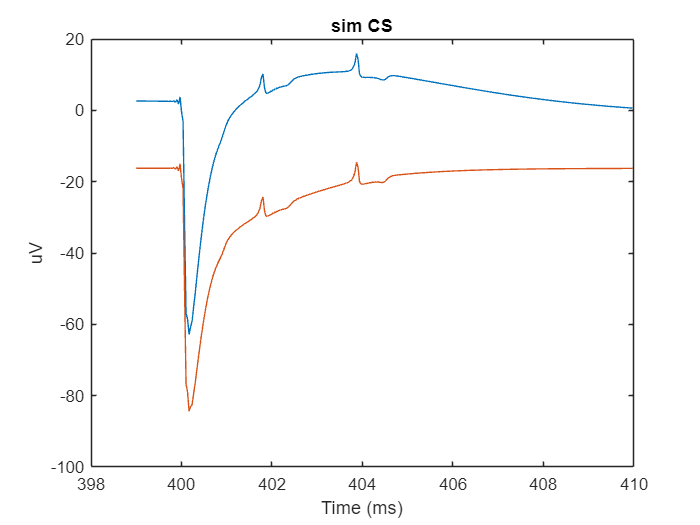

% cs segment
pre_ms = 1;
post_ms = 10;

% raw signal
% Units: ADC steps. To convert to electrode voltage in microvolts,
% multiply by 0.195.
raw = ephys_f(12,:);

figure;
plot(tvec(logical((tvec>(cs_timing-pre_ms/1000)).*(tvec<(cs_timing+post_ms/1000))))*1000,...
    raw(logical((tvec>(cs_timing-pre_ms/1000)).*(tvec<(cs_timing+post_ms/1000))))*1e6);
hold on;
plot(tvec(logical((tvec>(cs_timing-pre_ms/1000)).*(tvec<(cs_timing+post_ms/1000))))*1000,...
    ephys(12,logical((tvec>(cs_timing-pre_ms/1000)).*(tvec<(cs_timing+post_ms/1000))))*1e6);

title('sim CS');
xlabel('Time (ms)');
ylabel('uV');

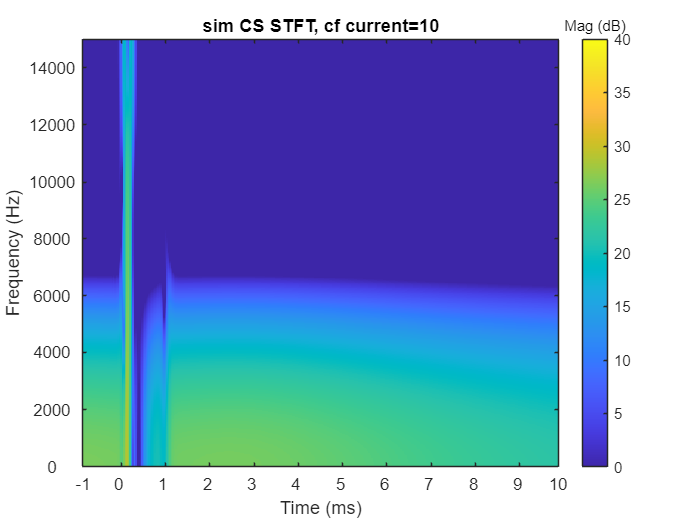

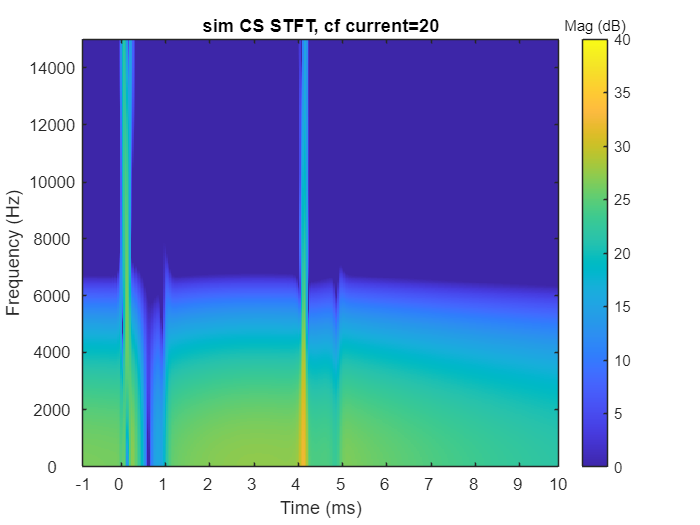

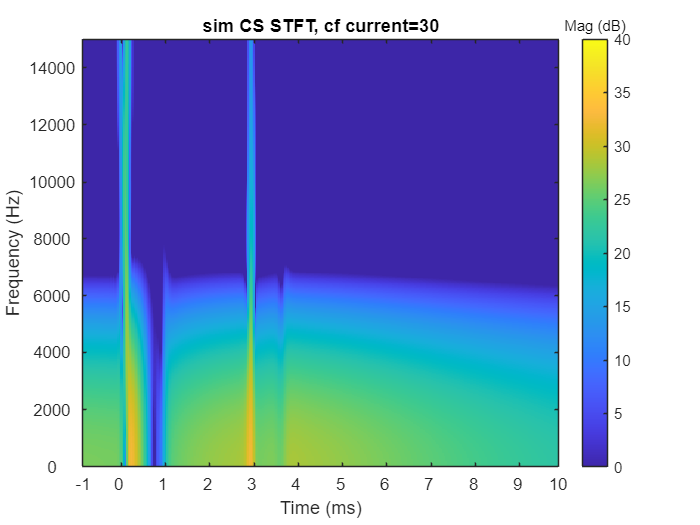

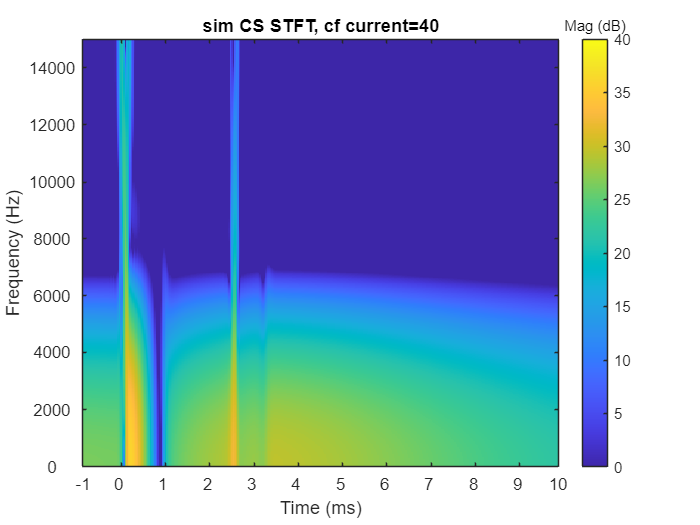

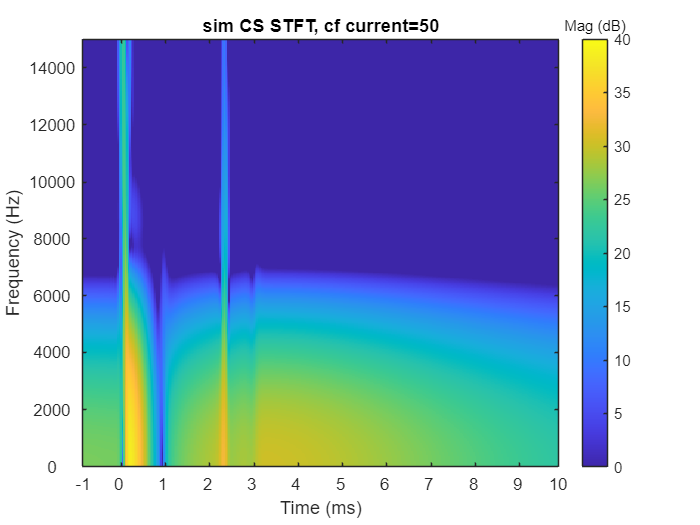

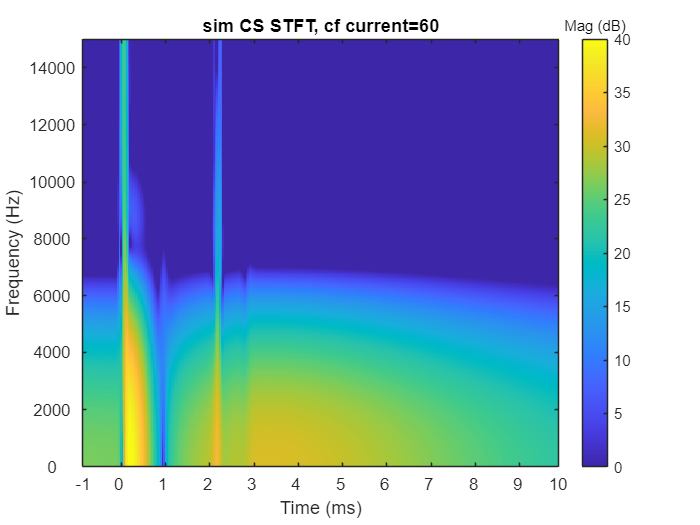

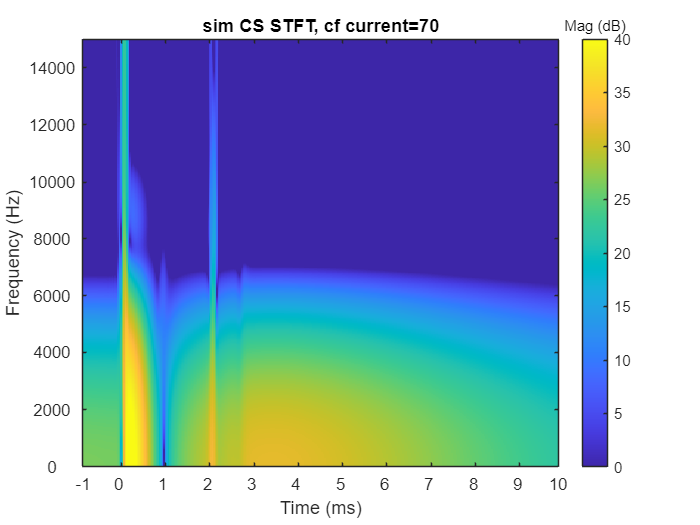

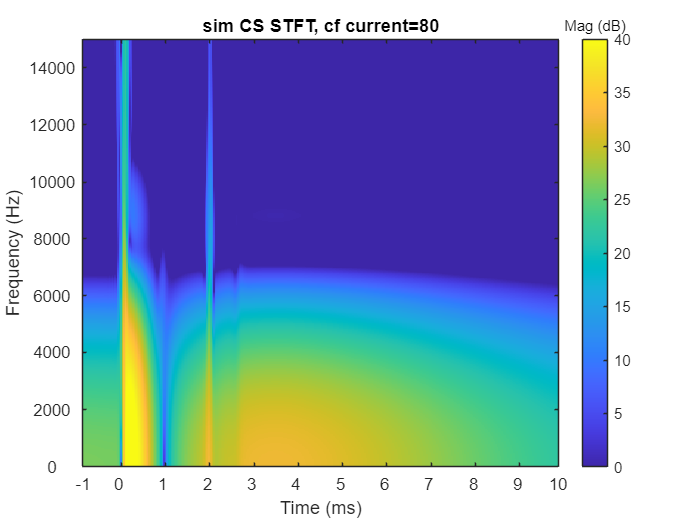

w = [];
s = [];
for i = 1:length(cf_current)

    raw = ephys_f(i,:);

    % stft
    WindowLength = 8;
    OverlapLength = WindowLength-1;
    FFTLength = 1024;

    temp = raw(logical((tvec>(cs_timing-pre_ms/1000)).*(tvec<(cs_timing+post_ms/1000))))*1e6;
    temp = temp - - mean(temp(1:0.5*fs_ms*pre_ms));
    [ss,f,t] = stft(temp,fs,...
        Window=hann(WindowLength,'periodic'),OverlapLength=OverlapLength,...
        FFTLength=FFTLength,FrequencyRange="onesided");
    ss = abs(ss);

    s(i,:,:) = ss;
    w(i,:) = temp;

    figure;
    imagesc(mag2db(squeeze(ss)));
    colormap('default');
    clim([0,40]);
    cb = colorbar;
    colorTitleHandle = get(cb,'Title');
    set(colorTitleHandle,'String','Mag (dB)');
    set(gca,'YDir','normal');
    xtlbl = [-pre_ms:post_ms];
    [~,xt] = min(abs(t-(xtlbl+pre_ms)/1000));
    set(gca, 'XTick',xt, 'XTickLabel',xtlbl, 'XTickLabelRotation',0);
    ytlbl = [0:2000:15000];
    [~,yt] = min(abs(f-ytlbl));
    set(gca, 'YTick',yt, 'YTickLabel',ytlbl);
    xlabel('Time (ms)');
    ylabel('Frequency (Hz)');
    title(['sim CS STFT, cf current=' num2str(cf_current(i))]);

end

% save
save('sim_cs_waveform.mat','s','w');